## **Assignment-IV**

**Department of Applied Mathematics**

**Noakhali Science and Technology University**

**Course Code: A.MTH 4102, Course Title: Math Practical -V (Using MATLAB)**

*“Everybody should learn to program a computer, because it teaches you how to think.”*

***Apple - Steve Jobs***

**Question-1:**  Write a MATLAB program that will create a text file containing tabular values of x vs y which  will imply that $\textrm{𝑦}=\frac{\textrm{𝑠𝑖𝑛𝑥}}{x}\;$tends to 1 as 𝑥 tends to 0.

**Answer:**

x = 0:.1:1;
A = [x; sin(x)./x];

fileID = fopen('tab1.txt','w');
fprintf(fileID,'%6s %12s\n','x','sin(x)/x');
fprintf(fileID,'%6.2f %12.8f\n',A);
fclose(fileID);

**Question-2:**  Obtain solution of $x^3 +\textrm{𝑝𝑥}+\textrm{𝑞}=0$ using symbolic coefficients. Also, find the roots of $2{\textrm{𝑥}}^3 -3\textrm{𝑥}+5=0\ldotp$

**Answer:**

syms x p q
eqn = x^3 + p*x + q;
eqn2 = 2*x^3 - 3*x + 5;
disp(solve(eqn));

$$\left(\begin{array}{c} \mathrm{root}\left(z^{3}+p\,z+q,z,1\right)\\ \mathrm{root}\left(z^{3}+p\,z+q,z,2\right)\\ \mathrm{root}\left(z^{3}+p\,z+q,z,3\right) \end{array}\right)$$

% disp(coeffs(eqn,[x]));
% disp(roots(coeffs(eqn,[x])));
% disp(roots(sym2poly(eqn)));
disp(roots(sym2poly(eqn2)));

  -1.7189 + 0.0000i
   0.8594 + 0.8461i
   0.8594 - 0.8461i



**Question-3:**  Consider integrating $\textrm{𝑓}\left(\textrm{𝑥}\right)={\textrm{𝑒}}^x -x^2$ over the interval 𝑥 = 0 to 1 using quadrature related  command codes. 

**Answer:**

myfun = @(x) exp(x)-x.^2;
% q = quad(myfun,0,1)
%quad() is not recommended
q = integral(myfun,0,1);
disp(q)

    1.3849



**Question-4:**  Use plot and/or ezplot, as appropriate, to graph the following functions (use grid): $\left(a\right)\textrm{𝑦}={\textrm{𝑥}}^3 -\textrm{𝑥}\;\textrm{for}-4\le \textrm{𝑥}\le 4$ $\left(b\right)\textrm{𝑦}={\textrm{𝑒}}^{-{\textrm{𝑥}}^2 }$ and $\left(c\right)\textrm{𝑦}={\textrm{𝑥}}^4 -{\textrm{𝑥}}^{2\;} \;\textrm{for}-2\le \textrm{𝑥}\le 2$

**Answer:**

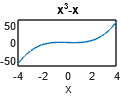

%(a)
ezplot('x^3-x',[-4 4])

%(b)
interval = [-2 2]

interval =     -2     2


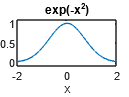

ezplot('exp(-x^2)', interval)

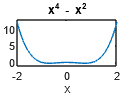

%(c)
ezplot('x^4 - x^2', interval)

**Question-5:**  Write a MATLAB code that will take n and show prime numbers upto a number n. Also, it will  print number of primes upto n. Test it for n=100. 

**Answer:**

clear all;
N=input('Prime Numbers until:');
if N<2
    return;
elseif N==2
    disp(2);
    return;
end
Pr(1)=2;Pr(2)=3;Count=3;
for i=4:N
%     C=Check(i);
    C=1;
    for k=2:(ceil(sqrt(i)))
        if mod(i,k)==0
            C=0;
        end
    end
    if C==1
        Pr(Count)=i;
        Count = Count +1;
    end
end
disp(Pr);

  Columns 1 through 13

     2     3     5     7    11    13    17    19    23    29    31    37    41

  Columns 14 through 25

    43    47    53    59    61    67    71    73    79    83    89    97



%  function C=Check(i)
%  C=1;
%  for k=2:(ceil(sqrt(i)))
%      if mod(i,k)==0
%         C=0;
%      end
%  end
%  end

**Question-6:**  Write a program that read any base value and argument for logarithmic operation. Hence,  evaluate ${\textrm{Log}}_{17} 29\ldotp$ 

**Answer:**

bag = input("Enter base and arg in [b ag] pair");
logb = @(X,b) log(X)/log(b);
disp(logb(bag(1),bag(2)));

    0.8414



disp(logb(17,29))

    0.8414



**Question-7:**  Write a MATLAB program that will read a number and will message whether it is prime or not  using both MATLAB library function and user-defined function. Test it for 79 and 87.

**Answer:**

%matlab library function

a = input("Enter a value")

a = 79

if isprime(a)
    fprintf("%d is prime",a)
else
    fprintf("%d is not prime",a)
end

79 is prime


%user defined function
isPrime(a)

79 is prime

**Question-8:**  Write a MATLAB code that will read two numbers and will print greatest common divisor  (GCD) and lowest common factor (LCM). Test it for 24 and 36.

**Answer:**

A = input("Enter  value  in [x,y]")

A =     24    36


fprintf("GCD is %d", gcd(A(1),A(2)))

GCD is 12

fprintf("LCM is %d", lcm(A(1),A(2)))

LCM is 72

**Question-9:**  Plot the piecewise defined function $f\left(x\right)=\left\lbrace \begin{array}{ll}
x^2  & \textrm{if}-1\le x\le 0\ldotp 5\;\\
0\ldotp 25 & \textrm{if}\;0\ldotp 5\le x\le 1
\end{array}\right.$

**Answer:**

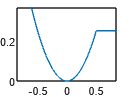

syms x

% not recommended, but use "y = piecewise(-1 <= x <= 0.5 ,x^2,0.5 <= x <= 1,0.25)";
y = piecewise((-1 <= x) & (x<= 0.5) ,x^2,(0.5 <= x)&(x <= 1),0.25);
fplot(y)

**Question-10:**  Create a MATLAB function for generating n-th Fibonacci number. Then, create another m-file  to generate list of first 10 Fibonacci numbers by function call. 

**Answer:**

n = input("enter a value");
fprintf("%dth fibonacci is %d",n,Fib(n));

4th fibonacci is 3

for i=1:10
    disp(Fib(i))
end

     1

     1

     2

     3

     5

     8

    13

    21

    34

    55



**Question-11:**  Using plot3 and ezplot command, obtain the graph of the curve represented by the parametric  equations: 𝑥 = 𝑐𝑜𝑠2𝜋𝑡, 𝑦 = 𝑠𝑖𝑛2𝜋𝑡, 𝑧 = 𝑡, −2 ≤ 𝑡 ≤ 2

**Answer:**

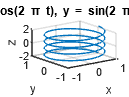

% ezplot(funx,funy,uinterval)
x = @(t) cos(2*pi*t);
y = @(t) sin(2*pi*t);
z = @(t) t;
int = [-2 2];

ezplot3(x,y,z,int);

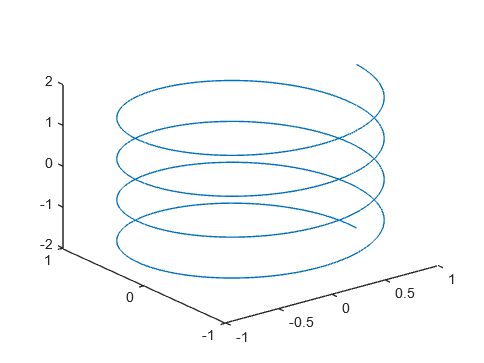


%using plot3
T = -2:0.01:2;
plot3(cos(2*pi*T), sin(2*pi*T), T)

**Question-12:**  Using ezsurf command generate the surfaces of the following functions:  


$$\left(a\right)\textrm{𝑓}\left(\textrm{𝑥},\textrm{𝑦}\right)=\textrm{𝑠𝑖𝑛𝑥}\textrm{𝑠𝑖𝑛𝑦},-3\textrm{𝜋}\le \textrm{𝑥},\textrm{𝑦}\le 3\textrm{𝜋}$$



$$\left(b\right)\textrm{𝑓}\left(\textrm{𝑥},\textrm{𝑦}\right)=\left({\textrm{𝑥}}^2 +{\textrm{𝑦}}^2 \right)\;\cos \left({\textrm{𝑥}}^2 +{\textrm{𝑦}}^2 \right),-1\le \textrm{𝑥},\textrm{𝑦}\le 1$$


**Answer:**

% newer matlab version not-recommended to use "ezsurf" insted of "fsurf"

f1 = @(x,y) sin(x).*sin(y);
f2 = @(x,y) (x.^2 + y.^2).*cos(x.^2 + y.^2);
fsurf(f1,[-3*pi 3*pi -3*pi 3*pi]);
fsurf(f2,[-1 1]);

**Question-13:**  Using symsum command, obtain the expression for ∑ 𝑘 2 , squared sum of first n consecutive  integers. Hence, find the symbolic exact value for n=10 and also approximate decimal value. 

**Answer:**

syms k x n
disp(symsum(k^2,k,0,n));

$$\frac{n\,\left(2\,n+1\right)\,\left(n+1\right)}{6}$$

disp(symsum(k^2,k,0,10));

$$385$$

%user-defined function

% function for check prime

function isprima = isPrime(n)
  b = mod(n,2);
  if n==1 || n==-1
      fprintf("%d is not prime",n);
      return
  elseif n==2 || n==-2
      fprintf("%d is prime",n)
      return
  elseif b==0 
      fprintf("%d is not prime",n)  
      return
  elseif b>0 
      for m = 3:2:sqrt(abs(n)) %instead of i = 3:2:(n-1)
          b = mod(n,m); 
          if b==0 
            fprintf("%d is not prime",n) 
          return 
          end
      end 
  end

      fprintf("%d is prime",n)
end


%===================fibonacci======================%
function y = Fib(n)
    phi = (1+sqrt(5))/2;
    y = round((phi^n-(-phi)^-n)/(2*phi-1));
end


  
